## **Rocket trajectory simulation **

## **Rubén Armando Figueroa Fuentes**

** With aid of ChatGPT, we will improve this repository over time**

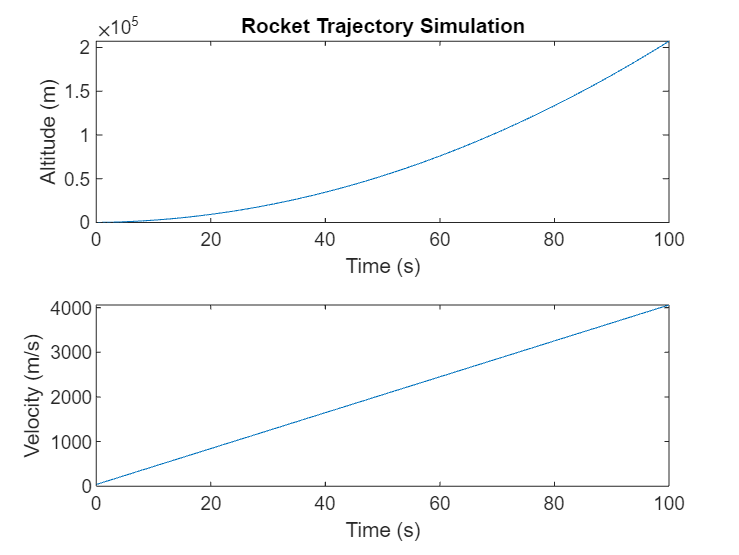

%Change code correctly 
% Rocket parameters
mass = 1000;         % kg
thrust = 50000;      % N (constant thrust for simplicity)
gravity = 9.81;      % m/s^2 (acceleration due to gravity)

% Simulation settings
total_time = 100;    % Total simulation time in seconds
time_step = 1;       % Time step for simulation in seconds

% Initialize variables
time = 0;
altitude = 0;
velocity = 0;

% Arrays to store simulation data
time_list = [];
altitude_list = [];
velocity_list = [];

% Simulation loop
while time <= total_time
    % Calculate net force (thrust - gravity)
    net_force = thrust - mass * gravity;
    
    % Calculate acceleration using Newton's second law (F = ma)
    acceleration = net_force / mass;
    
    % Update velocity and altitude using basic physics equations
    velocity = velocity + acceleration * time_step;
    altitude = altitude + velocity * time_step;
    
    % Append simulation data to arrays
    time_list = [time_list, time];
    altitude_list = [altitude_list, altitude];
    velocity_list = [velocity_list, velocity];
    
    % Increment time by the time step
    time = time + time_step;
end

% Plotting the results
subplot(2, 1, 1);
plot(time_list, altitude_list);
xlabel('Time (s)');
ylabel('Altitude (m)');
title('Rocket Trajectory Simulation');

subplot(2, 1, 2);
plot(time_list, velocity_list);
xlabel('Time (s)');
ylabel('Velocity (m/s)');


% Display the simulation results
fprintf('Maximum Altitude: %.2f meters\n', max(altitude_list));

Maximum Altitude: 207018.69 meters


fprintf('Time of Flight: %.2f seconds\n', total_time);

Time of Flight: 100.00 seconds



% Clear unused variables
clear net_force acceleration